# Create Deep Learning Network Architecture with Pretrained Parameters

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 12-Mar-2025 16:34:22

## Load Network Parameters

Load network parameters like weights, biases, or layers unsupported for network code generation from the stored parameters file.

params = load("params_2025_03_12__16_34_09.mat");

## Create dlnetwork

Create the dlnetwork variable to contain the network layers.

net = dlnetwork(featureInputLayer(47,"Name","input_1"));

## Add Layer Branches

Add branches to the dlnetwork. Each branch is a linear array of layers.

% Body Branch
tempNet = [
    fullyConnectedLayer(256, "Name", "Nx256 FC")
    reluLayer("Name", "relu_body")
    fullyConnectedLayer(256, "Name", "Nx256 FC2")
    reluLayer("Name", "body_output")
    ];
net = addLayers(net, tempNet);

% Mean Branch
tempNet = [
    fullyConnectedLayer(10, "Name", "Nx6 FC")
    tanhLayer("Name", "tanh ")
    scalingLayer("Name", "fc_mean")
    ];
net = addLayers(net, tempNet);

% Std Branch: Log-std branch (fc_std -> clamp -> exp)
tempNet = [
    fullyConnectedLayer(10, "Name", "fc_std")
    functionLayer(@(X) min(max(X, -10), 2), "Name", "clamp")
    functionLayer(@(X) exp(X), "Name", "std")
    ];
net = addLayers(net, tempNet);

% Clean up helper variable
clear tempNet;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

net = connectLayers(net,"body_output","Nx6 FC");
net = connectLayers(net,"input_1","Nx256 FC")

net =   dlnetwork with properties:

         Layers: [11×1 nnet.cnn.layer.Layer]
    Connections: [9×2 table]
     Learnables: [8×3 table]
          State: [0×3 table]
     InputNames: {'input_1'  'fc_std'}
    OutputNames: {'fc_mean'  'std'}
    Initialized: 0

  View summary with summary.


net = connectLayers(net,"body_output","fc_std");
net = initialize(net);

## Plot Layers

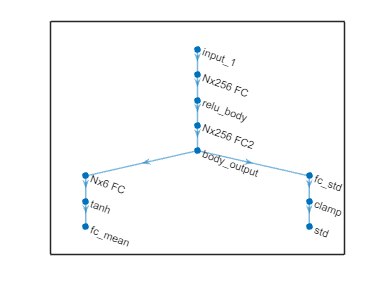

plot(net);

%ax = gca;
%set(gcf, 'Position', [100, 100, 1000, 800]); 
%print(gcf, 'layers.png', '-dpng', '-r800');